# Multiclass classification with neural networks - IRIS

You will develop a framework to solve a multiclass classification problem with a neural network and conjugate gradient descent. This week we will only consider an Artificial Neural Network with a single hidden layer (a so called shallow network). For simplicity, we will only consider one split of the data and a fixed set of hyperparameters. However, you should feel free to consider a model selection and error estimation procedure for this algorithm.

## Set up Environment

clc, clear, close all

Store the functions you generate in this tutorial in `lib`. In order to run this code you will need the following functions:

- `fmincg.m `(Supplied in the Week 9 `lib` folder on MyPlace)

- `nnCostFunction.m `(Developed in Tutorial 9a)

- `rand_initialize.m `(Developed in Tutorial 9b)

- `predict.m `(Copied from Week 7 - but please note we are required to adapt this function to work with the framework developed in this tutorial)

- `scaling.m` (Developed in Week 4)

addpath('lib')
addpath('Data')

## Load Iris Data

We will now use the iris data set as an example for soving an optimisation problem with congugate gradient descent utilising the Newton Method. You can refer to Week 2 for data visualisation for the iris data set.

load("Iris_database.mat")
[n, m] = size(iris);
X = iris(:, [1:4]);
y = iris(:, end);
nclasses = length(unique(y));
rng(1);

features = {'Sepal Length [mm]', 'Sepal Width [mm]', 'Petal Length [mm]', 'Petal Width [mm]'};
name = {'Setosa'; 'Versicolor'; 'Virginica'};

Determine the cardinality of each class.

nsetosa = sum(y==1);
nversicolor = sum(y==2);
nvirginica = sum(y==3);
nmin = min([nsetosa, nversicolor, nvirginica]);
fprintf('Size of the data set is: [%i, %i]', n, m)

Size of the data set is: [150, 5]

## Split the data

Split the data into training and testing sets.

rng(1)
r = 0.7; % proportion of training to testing set
ind = randperm(n);

ntr = round(r*n);
itr = ind(1:ntr);  % train inds
it = ind(ntr+1:end);  % test inds

Xtrain = X(itr, :); ytr = y(itr);
Xtest = X(it, :); yt = y(it);

Histogram of training and testing sets

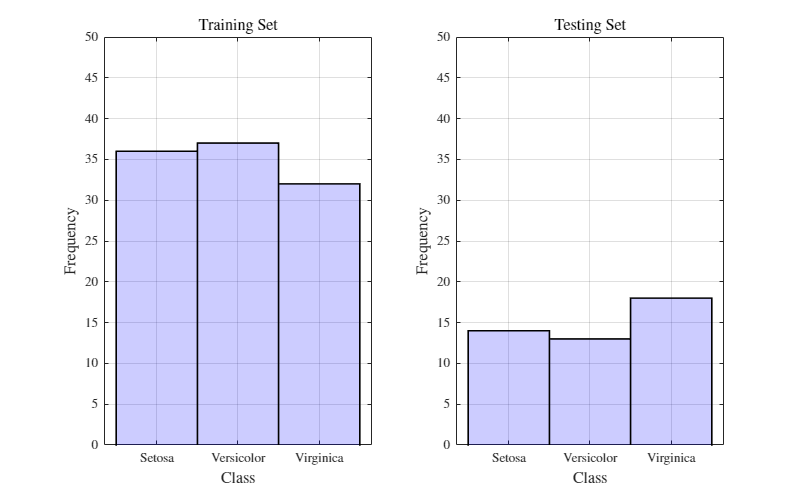

figure('position',[0,0,800,500])
set(groot,'defaultAxesTickLabelInterpreter','latex');

subplot(1,2,1), hold on, grid on, box on
histogram(ytr, 'FaceColor', "b", 'FaceAlpha', 0.2, "EdgeColor", 'k', 'LineWidth', 1.2)
xlabel('Class', 'FontSize', 12, 'interpreter', 'latex');
xticks([1, 2, 3]); xticklabels(name);
ylabel('Frequency', 'FontSize', 12, 'interpreter', 'latex');
title('Training Set', 'FontSize', 12, 'interpreter', 'latex')
set(gca,'Ylim',[0 50])

subplot(1,2,2), hold on, grid on, box on
histogram(yt, 'FaceColor', "b", 'FaceAlpha', 0.2, "EdgeColor", 'k', 'LineWidth', 1.2)
xlabel('Class', 'FontSize', 12, 'interpreter', 'latex');
xticks([1, 2, 3]); xticklabels(name);
ylabel('Frequency', 'FontSize', 12, 'interpreter', 'latex');
title('Testing Set', 'FontSize', 12, 'interpreter', 'latex')
set(gca,'Ylim',[0 50]) 

Your plot should look like this:

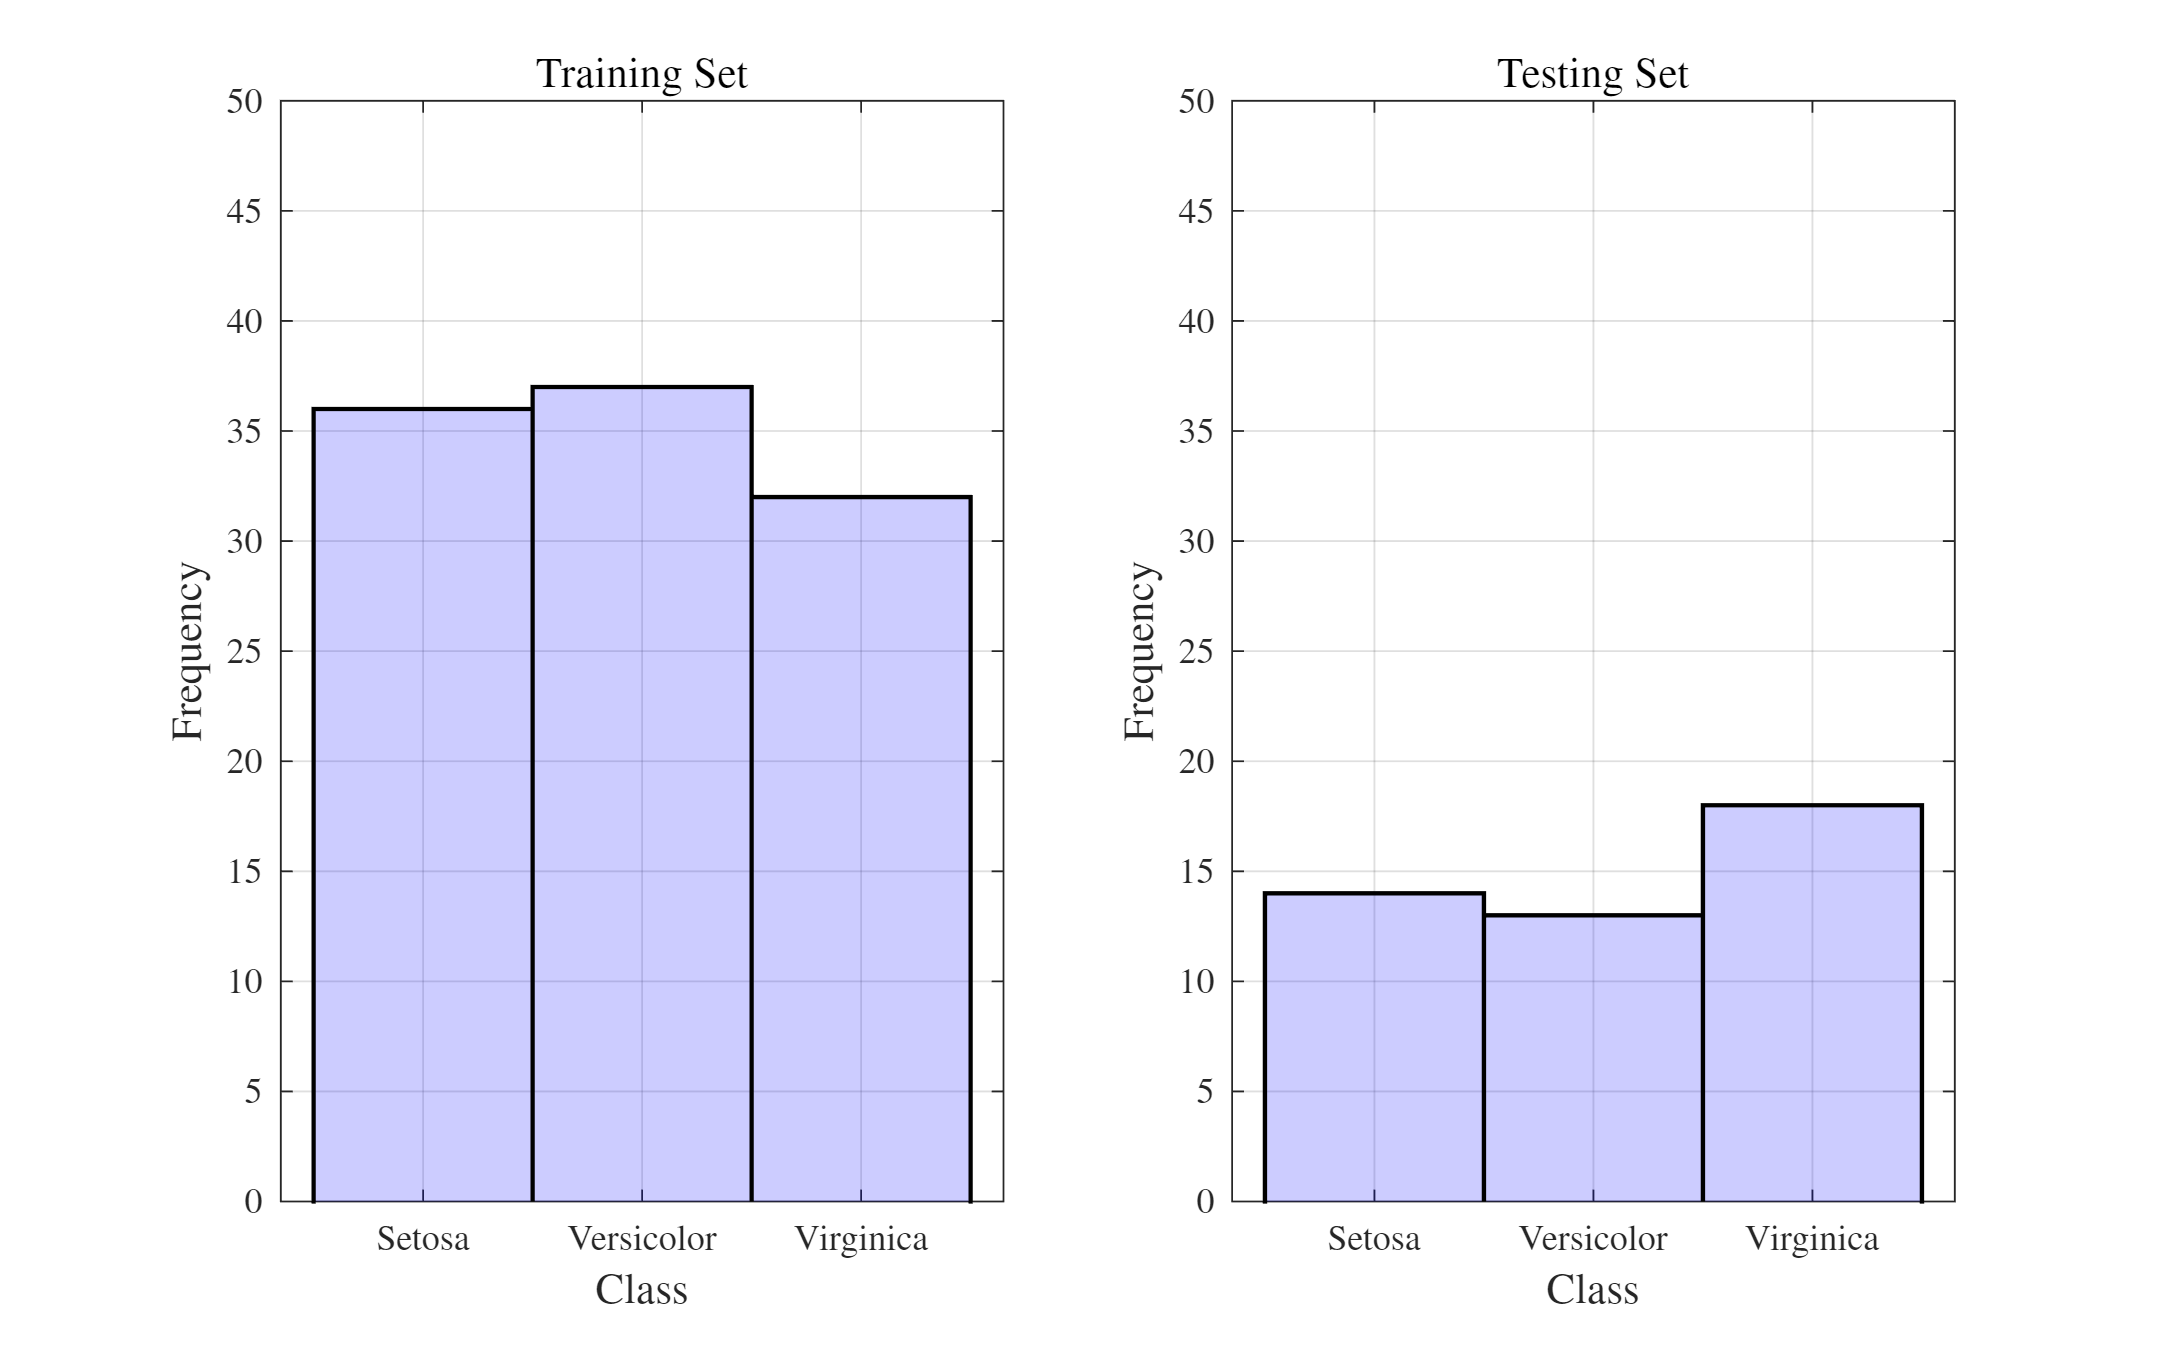

## Scale the Data

Scale the Training and Testing sets between -1 and 1.

type=3;
[Xtrain, Xtest, mi, di] = scaling(Xtrain,Xtest,[-1, 1]);

## Initialize model

#### Model Hyperparameters

Since we will use the fmincg.m function for conjugate gradient descent we do not need to specify a learning rate.

niter = 100; % number of iterations
lambda = 0.001; % regularisation parameter
act_fun = 'sigmoid'; % activation function
options = optimset('MaxIter', niter, 'Display', 'off'); % optimiser settings

#### Architecture

In this case there is 1 hidden layers, we recommend fixing the number of hidden neurons to 15. The required number of neurons in the input layer is a function of the input X, and similarly, the required number of output neurons is a function of the target variable y.

n_input = size(Xtrain, 2);
n_hidden = 15;
n_output = length(unique(y));

layers = {n_input, n_hidden, n_output};
fprintf('Expected network shape is: (%i, %2i, %i)\nNetwork shape is: (%i, %2i, %i)', [4, 15, 3], layers{:})

Expected network shape is: (4, 15, 3)
Network shape is: (4, 15, 3)

#### Weights

IInitialize the weights and wrap them into a single column vector

nlayers = length(layers);
rng(1)
nW = 2;  % number of layers minus 1

W1 = weights_init(n_input, n_hidden);
W2 = weights_init(n_hidden, n_output);
W0 = [W1(:); W2(:)];

fprintf('Expected shape for W0: (%2i, %2i)\nShape for W0 is: (%2i, %2i)', [123, 1], size(W0))

Expected shape for W0: (123,  1)
Shape for W0 is: (123,  1)

## **Encode y vector**

y_encoded = zeros(size(y, 1), n_output);
for i = 1:length(y)
    if y(i) == 1
        y_encoded(i, 1) = 1;
    elseif y(i) == 2
        y_encoded(i, 2) = 1;
    else
        y_encoded(i, 3) = 1;
    end
end
y = y_encoded;

## Build a model using fmincg.m

Define the nnCostFunction in terms of a parameter using the @ notation, e.g, @(w) and call the solver using your cost function handle, initialized weights and options.

cost_func = @(W) nnCostFunction(W, n_input, n_hidden, n_output, Xtrain, ytr, lambda, act_fun);
alpha = 1e-5;
tol = 1e-6;
maxIter = 200;
[w_opt, f_opt, f_his, itt] = gd(cost_func, W0, alpha, tol, maxIter);

itt: 200

disp(f_opt)

    3.4457



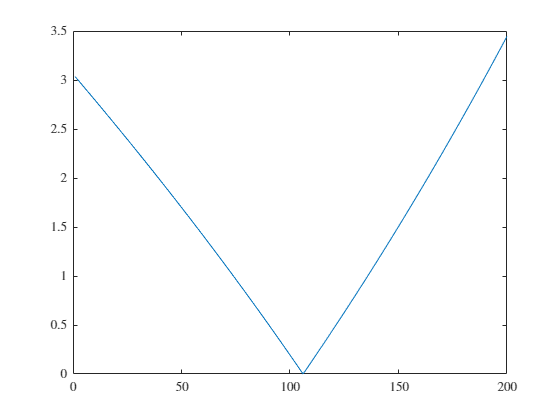

figure();
plot(1:itt, abs(f_his));

## Reshape the weights into the weight matricies for each layer

The weights are currently in the column vector W and should be reshaped into w1 and w2 for the two layers of the network

addpath('lib/utils')
W_cell = reshape_weights_vector(W, n_input, n_hidden, n_output);
w1 = W_cell{1};
w2 = W_cell{2};
fprintf('Expected shape for w1: (%2i, %2i)\nExpected shape for w2: (%2i, %2i)', 15, 5, 3, 16)
fprintf('Shape for w1 is: (%2i, %2i)\nShape for w2 is: (%2i, %2i)', size(w1), size(w2))

## Evaluate performance on the training set

You will need to adapt your predict function in several ways to work with the neural network framework we have developed. The most obvious one is that we now need to include a handle for the activation function in the same way that you did for the file `nnCostFunction`. Additionally, we need the predict function to take the set of weights (w1 and w2) and to handle the bias unit in the same way you have done for the file `nnCostFunction`.

E.g., `[pr,pc] = predict(w1, w2, Xtrain, act_fun)`

#### Function Inputs                                                        Function Outputs

Weights - $w_1, w_2$                                                               Probability - `pr`

Input data - $X$                                                                  Corresponding class - `pc`

Activation Function - act_fun

[pc] = ones(size(ytr));
for c = 1:3
    fprintf('Expected accuracy for %s:    \t%i %%\n', name{c}, 100)
end
pc = predict(Xtrain, {W1, W2}, act_fun); %%% <--- your function here
for c = unique(ytr)'
    i = ytr==c;
    acc = sum(pc(i) == ytr(i)) / sum(i);
    fprintf('Training set accuracy for %s:\t%i %%\n', name{c}, round(acc*100))
end

## Evaluate the model on the test set

Perform the forward phase on the test set to obtain a prediction for the unseen data.

expected = [100,100,94];
[pc] = ones(size(yt));
for c = 1:3
    fprintf('Expected accuracy for %s:    \t%i %%\n', name{c}, expected(c))
end
% [q, pc] = predict(w1, w2, Xtest, act_fun); %%% <--- your function here
for c = unique(yt)'
    i = yt==c;
    acc = sum(pc(i) == yt(i)) / sum(i);
    fprintf('Test set accuracy for %s:    \t%i %%\n', name{c}, round(acc*100))
end

## Evaluate Confusion Matrix

Determine the confution matrix for the test set.

fprintf('Expected Confusion Matrix:\t[%2i, %2i, %2i\n\t\t\t\t %2i, %2i, %2i\n\t\t\t\t %2i, %2i, %2i]',...
    14, 0, 0, 0, 13, 0, 0, 1, 17);
cmmat  = confusionmat(yt, pc);
fprintf('Confusion Matrix is:\t[%2i, %2i, %2i\n\t\t\t %2i, %2i, %2i\n\t\t\t %2i, %2i, %2i]',...
    cmmat(1, 1),  cmmat(1, 2),  cmmat(1, 3),...
    cmmat(2, 1), cmmat(2, 2), cmmat(2, 3),...
    cmmat(3, 1),  cmmat(3, 2),  cmmat(3, 3))